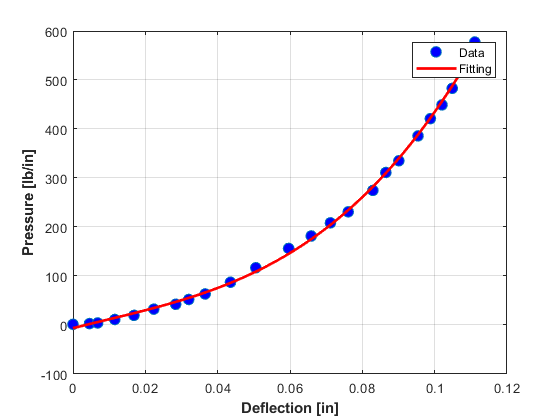

x = [0, 0.004542586750788643, 0.006813880126182965, 0.011545741324921135, 0.016845425867507886, 0.022334384858044162, 0.02839116719242902, 0.03198738170347003, 0.036529968454258675, 0.043533123028391164, 0.050536277602523653, 0.05962145110410094, 0.06586750788643532, 0.07116719242902207, 0.07608832807570977, 0.08290220820189274, 0.08649842271293375, 0.09009463722397476, 0.09539432176656151, 0.09880126182965299, 0.10201892744479495, 0.10485804416403785, 0.11110410094637223];
y = [1.408450704225352, 2.816901408450704, 4.225352112676056, 11.267605633802816, 19.718309859154928, 32.394366197183096, 42.25352112676056, 52.112676056338024, 63.38028169014084, 87.32394366197182, 116.90140845070422, 156.33802816901408, 181.6901408450704, 208.4507042253521, 230.98591549295773, 274.6478873239436, 311.2676056338028, 335.2112676056338, 385.91549295774644, 421.12676056338023, 449.2957746478873, 483.09859154929575, 577.4647887323944];

% Perform cubic regression
degree = 3;  % Degree of the polynomial (cubic regression)
coefficients = polyfit(x, y, degree);

% Generate a finer x-axis for smoother plotting
x_fit = linspace(min(x), max(x), 100);

% Evaluate the polynomial at the finer x-axis points
y_fit = polyval(coefficients, x_fit);

% Plot the original data and the cubic regression curve
figure;
plot(x, y, 'o', 'MarkerFaceColor', 'b', 'MarkerSize', 8);  % Original data
hold on;
plot(x_fit, y_fit, 'r-', 'LineWidth', 2);  % Cubic regression curve
hold off;

xlabel('Deflection [in]', 'FontWeight', 'bold');
ylabel('Pressure [lb/in]', 'FontWeight', 'bold');
legend('Data', 'Fitting');

grid on;

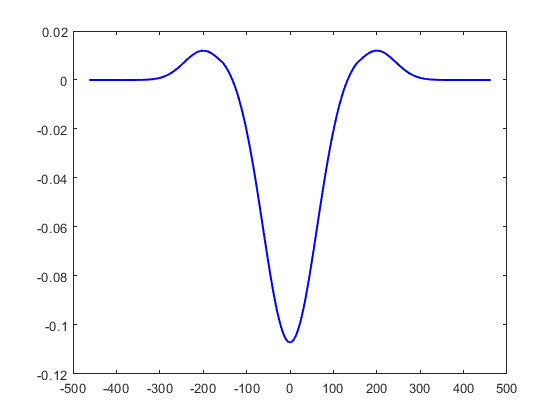

% Parameters
mu = 0;         % Mean of the normal distribution
sigma = 1;      % Standard deviation of the normal distribution
x1 = linspace(-6, 6, 1000);  % Range of x values

% Generate normal distribution
y1 = -1*normpdf(x1, mu, sigma);


y =-1*y1;

% Plot the curve
scx = 0.7;
scy = 0.1;
px = 3.2;
py = 0.042;

x2 = x1*scx+px;
y2 = y*scy-py;

x3 = x1*scx-px;
y3 = y*scy-py;

fx = [];
fy = [];
for i = 1:length(x3)
    if(x3(i)<-2.5)
        fx = [fx x3(i)];
        fy = [fy y3(i)];
    end
end
for i = 1:length(x1)
    if(x1(i)>-2.5 && x1(i)<2.5)
        fx = [fx x1(i)];
        fy = [fy y1(i)];
    end
end
for i = 1:length(x2)
    if(x2(i)>2.5)
        fx = [fx x2(i)];
        fy = [fy y2(i)];
    end
end
fy = fy -fy(1);
fx = fx * (500/8);
fy = fy * (0.12/0.4);
plot(fx,fy,'b-','LineWidth',1.5)
hold on

% plot(fx,fy*0.9)
% plot(fx,fy*0.7)
% plot(fx,fy*0.6)
% hold off
% 
% plot(x1, y1,'g', 'LineWidth', 2);
% hold on
% 
% plot(x2, y2,'r','LineWidth', 2);
% plot(x3, y3,'r','LineWidth', 2);
% title('Bell Curve with Slight Downturns');
% xlabel('X-axis');
% ylabel('Y-axis');
% grid on;
% hold off

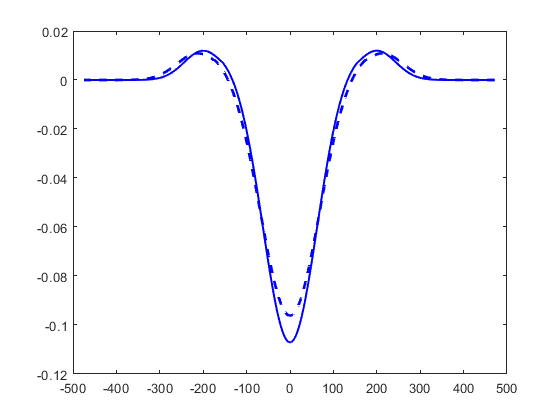


% Parameters
mu = 0;         % Mean of the normal distribution
sigma = 1.1;      % Standard deviation of the normal distribution
x1 = linspace(-6, 6, 1000);  % Range of x values

% Generate normal distribution
y1 = -1*normpdf(x1, mu, sigma);


y =-1*y1;

% Plot the curve
scx = 0.7;
scy = 0.1;
px = 3.4;
py = 0.042;

x2 = x1*scx+px;
y2 = y*scy-py;

x3 = x1*scx-px;
y3 = y*scy-py;

fx = [];
fy = [];
for i = 1:length(x3)
    if(x3(i)<-2.8)
        fx = [fx x3(i)];
        fy = [fy y3(i)];
    end
end
for i = 1:length(x1)
    if(x1(i)>-2.8 && x1(i)<2.8)
        fx = [fx x1(i)];
        fy = [fy y1(i)];
    end
end
for i = 1:length(x2)
    if(x2(i)>2.8)
        fx = [fx x2(i)];
        fy = [fy y2(i)];
    end
end
f1 = fx;
f2 = fy;
f2= f2 -f2(1);f1 = f1 * (500/8);
f2 = f2 * (0.12/0.4);
plot(f1,f2,'b--','LineWidth',2)

% 
% plot(x1, y1,'g', 'LineWidth', 2);
% hold on
% 
% plot(x2, y2,'r','LineWidth', 2);
% plot(x3, y3,'r','LineWidth', 2);
% title('Bell Curve with Slight Downturns');
% xlabel('X-axis');
% ylabel('Y-axis');
% grid on;
% hold off
% plot(fx,fy)

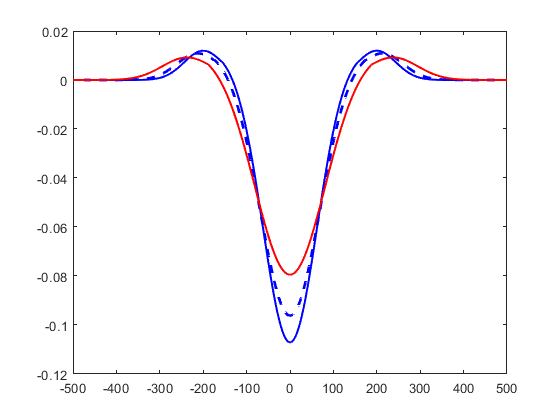


% Parameters
mu = 0;         % Mean of the normal distribution
sigma = 1.3;      % Standard deviation of the normal distribution
x1 = linspace(-6, 6, 1000);  % Range of x values

% Generate normal distribution
y1 = -1*normpdf(x1, mu, sigma);


y =-1*y1;

% Plot the curve
scx = 0.7;
scy = 0.1;
px = 3.8;
py = 0.042;

x2 = x1*scx+px;
y2 = y*scy-py;

x3 = x1*scx-px;
y3 = y*scy-py;

fx = [];
fy = [];
for i = 1:length(x3)
    if(x3(i)<-3)
        fx = [fx x3(i)];
        fy = [fy y3(i)];
    end
end
for i = 1:length(x1)
    if(x1(i)>-3 && x1(i)<3)
        fx = [fx x1(i)];
        fy = [fy y1(i)];
    end
end
for i = 1:length(x2)
    if(x2(i)>3)
        fx = [fx x2(i)];
        fy = [fy y2(i)];
    end
end
f1 = fx;
f2 = fy;
f2= f2 -f2(1);
f1 = f1 * (500/8);
f2 = f2 * (0.12/0.4);
plot(f1,f2,'r-','LineWidth',1.5)


% plot(x1, y1,'g', 'LineWidth', 2);
% hold on
% 
% plot(x2, y2,'r','LineWidth', 2);
% plot(x3, y3,'r','LineWidth', 2);
% title('Bell Curve with Slight Downturns');
% xlabel('X-axis');
% ylabel('Y-axis');
% grid on;
% hold off
% plot(fx,fy)

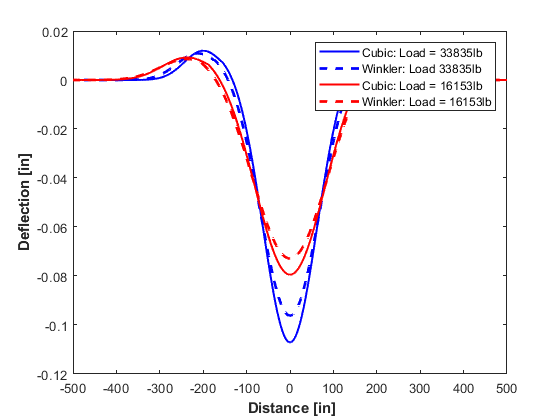



% Parameters
mu = 0;         % Mean of the normal distribution
sigma = 1.4;      % Standard deviation of the normal distribution
x1 = linspace(-6, 6, 1000);  % Range of x values

% Generate normal distribution
y1 = -1*normpdf(x1, mu, sigma);


y =-1*y1;

% Plot the curve
scx = 0.7;
scy = 0.1;
px = 3.8;
py = 0.042;

x2 = x1*scx+px;
y2 = y*scy-py;

x3 = x1*scx-px;
y3 = y*scy-py;

fx = [];
fy = [];
for i = 1:length(x3)
    if(x3(i)<-3.3)
        fx = [fx x3(i)];
        fy = [fy y3(i)];
    end
end
for i = 1:length(x1)
    if(x1(i)>-3.3 && x1(i)<3.3)
        fx = [fx x1(i)];
        fy = [fy y1(i)];
    end
end
for i = 1:length(x2)
    if(x2(i)>3.3)
        fx = [fx x2(i)];
        fy = [fy y2(i)];
    end
end
f1 = fx;
f2 = fy;
f2= f2 -f2(1);
f1 = f1 * (500/8);
f2 = f2 * (0.12/0.4);
plot(f1,f2,'r--','LineWidth',2)
xlabel(' Distance [in]', 'FontWeight', "bold");
ylabel('Deflection [in]', 'FontWeight', 'bold');
legend('Cubic: Load = 33835lb','Winkler: Load 33835lb','Cubic: Load = 16153lb','Winkler: Load = 16153lb');

hold off


% plot(x1, y1,'g', 'LineWidth', 2);
% hold on
% 
% plot(x2, y2,'r','LineWidth', 2);
% plot(x3, y3,'r','LineWidth', 2);
% title('Bell Curve with Slight Downturns');
% xlabel('X-axis');
% ylabel('Y-axis');
% grid on;
% hold off
% plot(fx,fy)